# Day 6 - Initial Data Visualizations

[lr_accel, lr_gyro] = parsePowerSenseData_1('12inchtest_90bpm.csv');

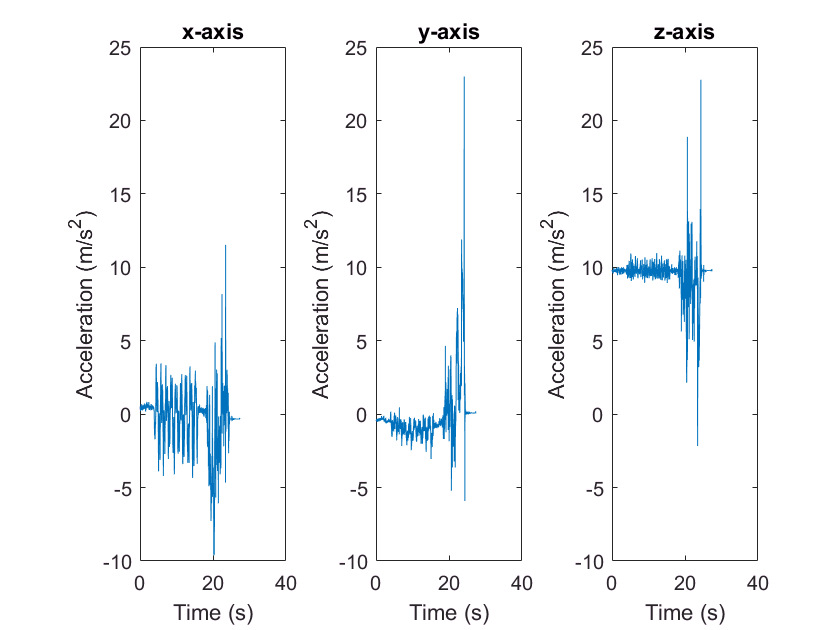

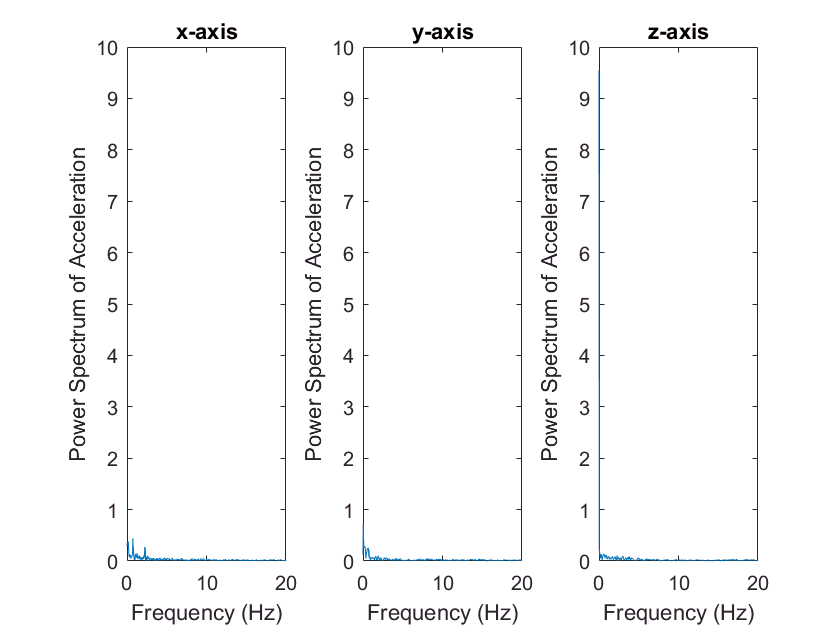

makeAccelerometerPlots(lr_accel,[],true)

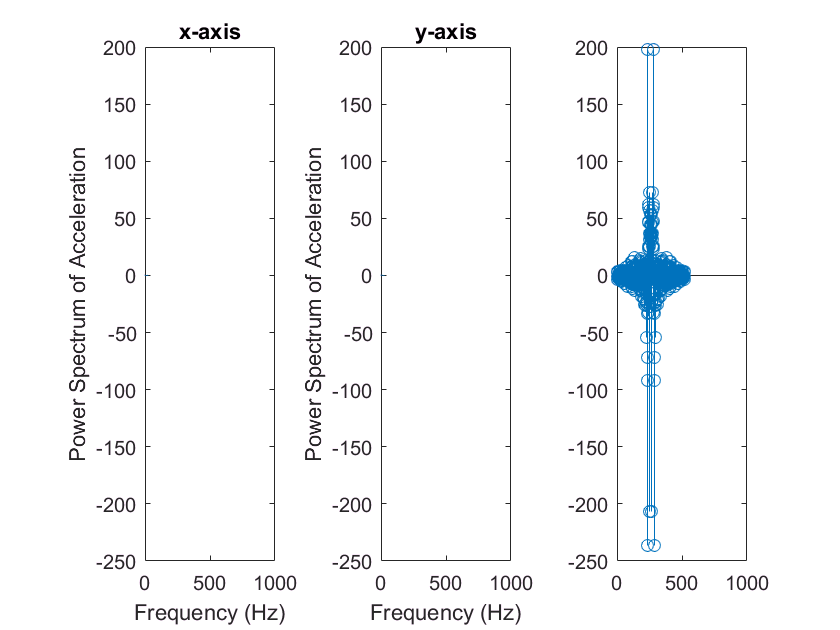

startcut = 280;
endcut = 800;

x_accel = lr_accel(:,2);
x_accel = x_accel(startcut:endcut);
plot(x_accel)
fft_x = real(fft(x_accel));
fft_xshift = fftshift(fft_x);

[~, i] = max(fft_xshift);
stem(fft_xshift)

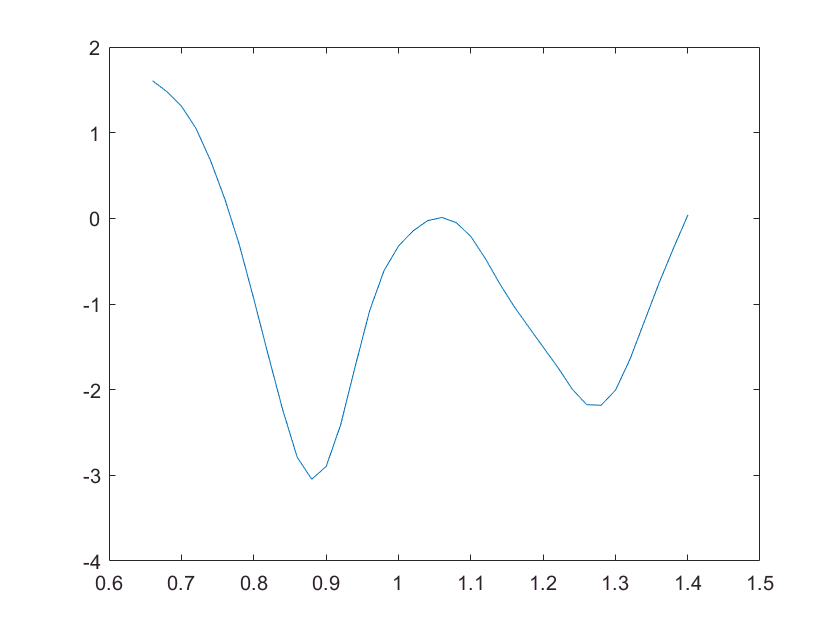

Fs = 1/lr_accel(2,1)-(lr_accel(1,1));

% make_freq_plot(x_accel, Fs)


h = [1/4 1/4 1/4 1/4];          % moving average shape
x_accel = conv(x_accel, h);     % moving average convolution
x_accel = x_accel(1:(end-length(h)+1)); % adjusting for conv
x_accel = conv(x_accel,h);      % move the average again
x_accel = x_accel(1:(end-length(h)+1)); % adjusting for conv
x_times = lr_accel(:,1);        % grab times column
x_times = x_times(startcut:endcut);     % cutoff bad data
x_times = x_times-x_times(1);   % center unex times

period1 = 34:71;
xacc_int = x_accel(period1);
xtime_int = x_times(period1);

velocity = cumtrapz(xtime_int, xacc_int);
position = cumtrapz(xtime_int, velocity);

figure
plot(xtime_int, xacc_int)

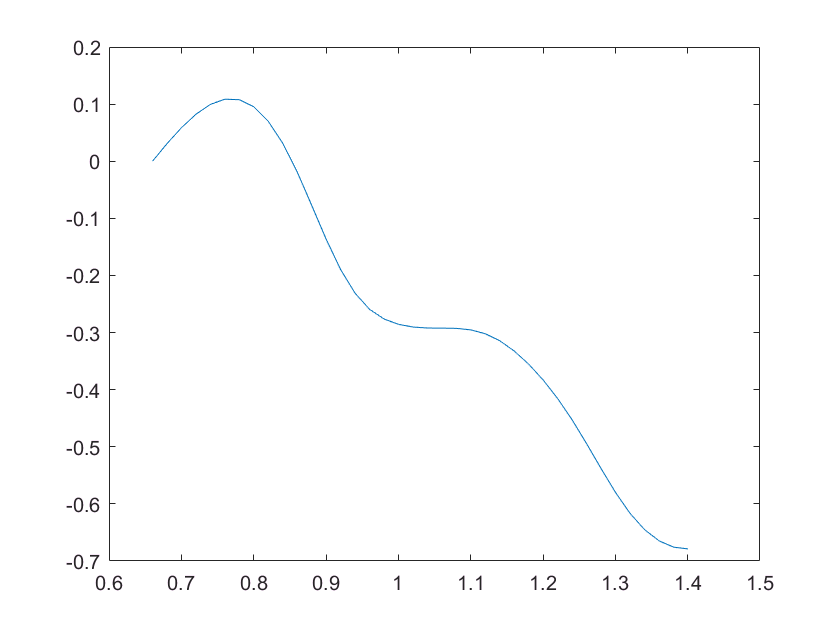

plot(xtime_int, velocity)

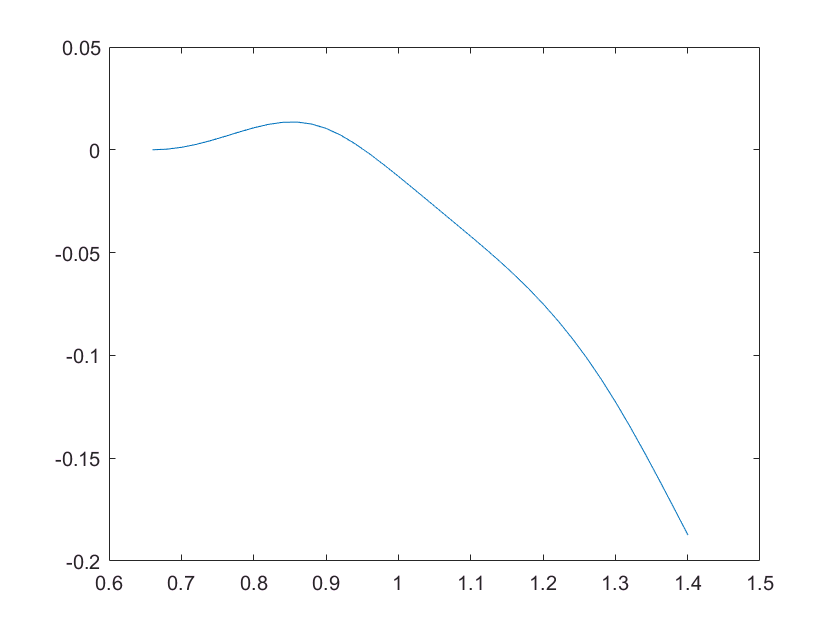

plot(xtime_int, position) 

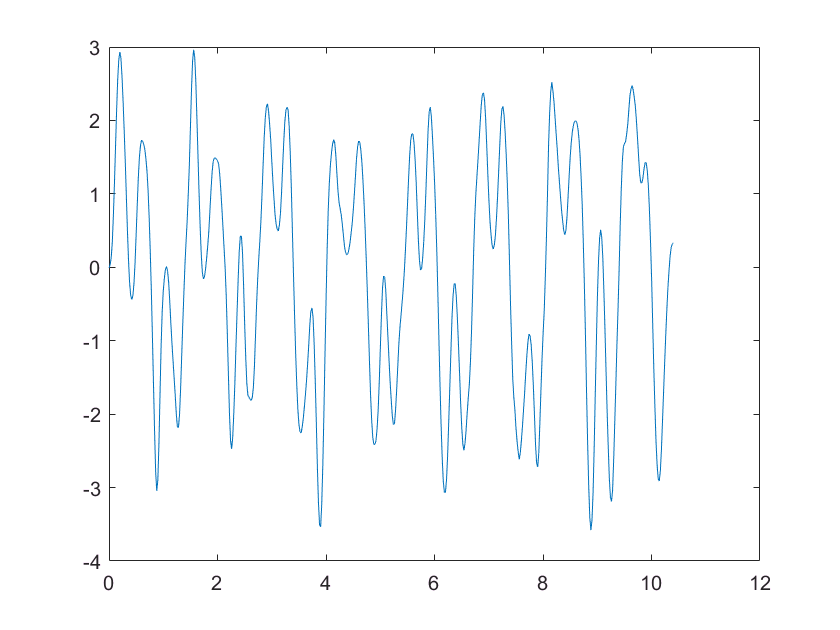

plot(x_times, x_accel)

# Square Conducting Analysis

[square_accel, square_gyro] = parsePowerSenseData_1('square90bpm.csv');

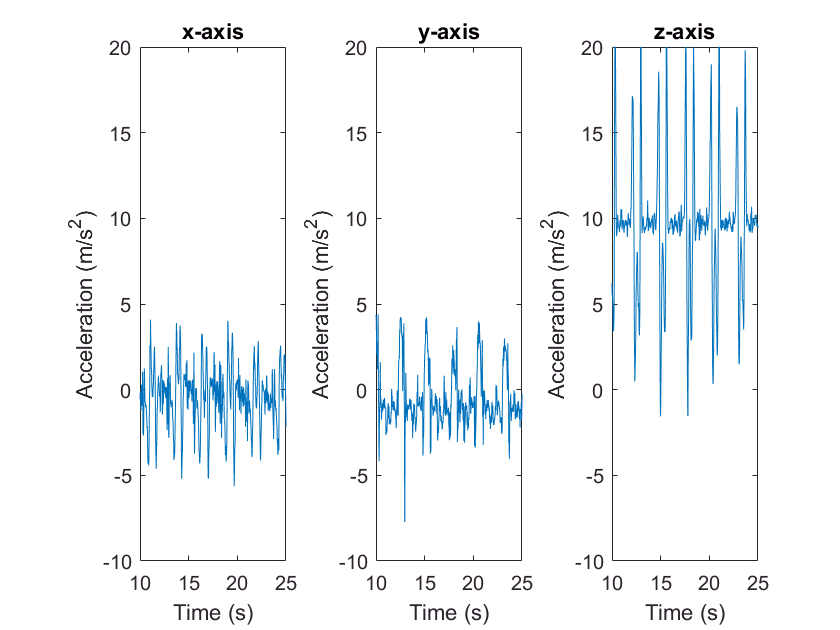

figure
[psquare_accel, psquare_gyro] = parsePowerSenseData_1('anil_perfect_square.csv');
makeAccelerometerPlots(psquare_accel,[], false)
ylim([-10 20])
xlim([10 25])

x_times = psquare_accel(:,1);    % grab times column
%x_times = x_times(100:750);  
x_times = x_times();  % cutoff bad data
x_times = x_times-x_times(1);   % center unex times
%z_accel_psquare = psquare_accel(100:750,4)
z_accel_psquare = psquare_accel(1:end,4)

z_accel_psquare =     9.5437
    9.5450
    9.4140
    9.3523
    9.6487
    9.6514
    9.8689
    9.9471
   10.1520
   10.3071


x_accel_psquare = psquare_accel(1:end,2)

x_accel_psquare =     0.6091
    0.6151
    0.6741
    0.7339
    0.3067
    0.5402
    0.6174
    0.2225
    0.0997
    0.2281


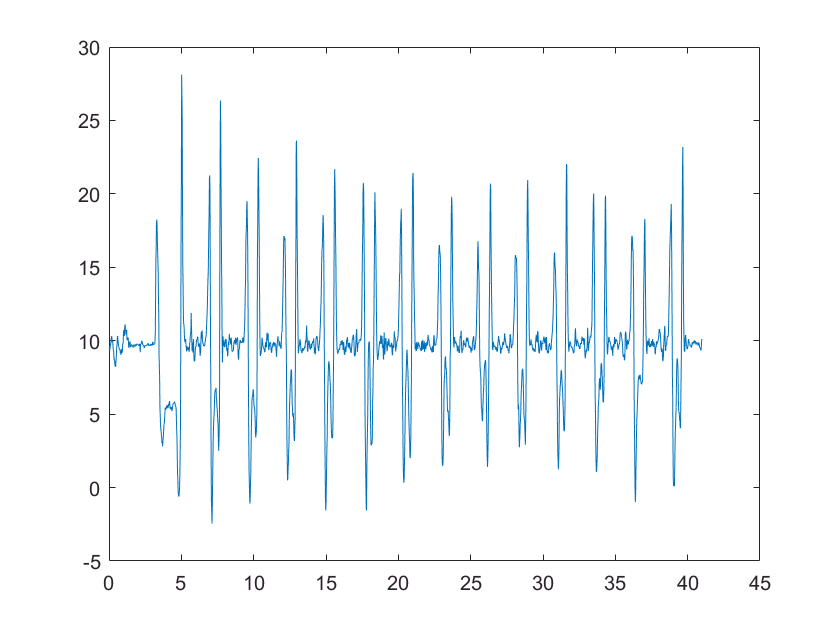

figure
plot(x_times, z_accel_psquare)

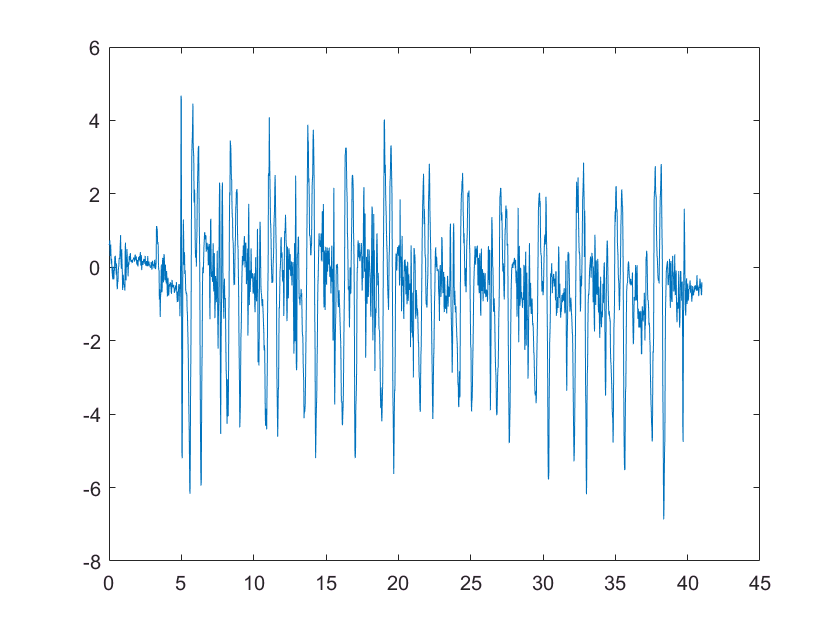

plot(x_times, x_accel_psquare)

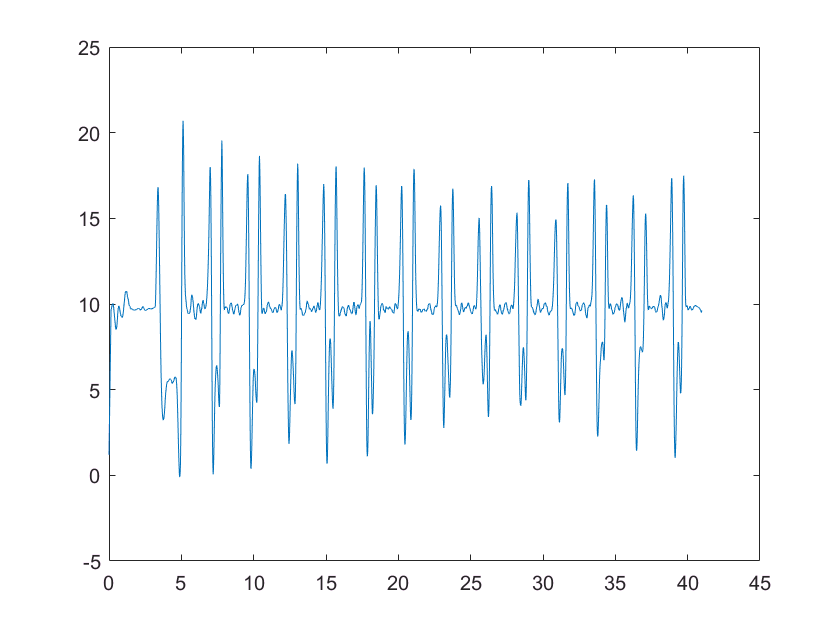


num = 8;
h = ones(1, num)./num;

%xacc = conv(xacc, h);
zacc = conv(z_accel_psquare, h);
zacc = zacc(1:end-length(h)+1);
plot(x_times,zacc)

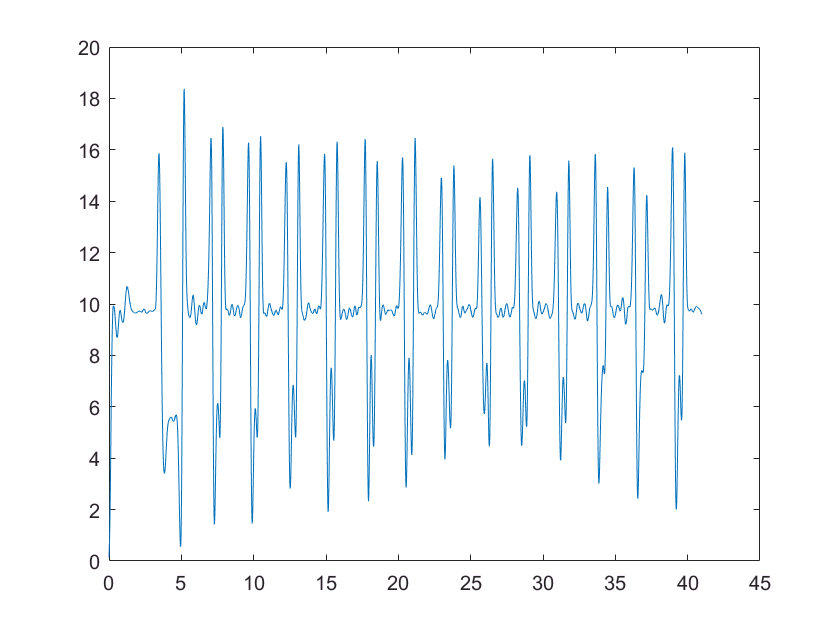

zacc = conv(zacc, h);
zacc = zacc(1:end-length(h)+1);
plot(x_times,zacc)

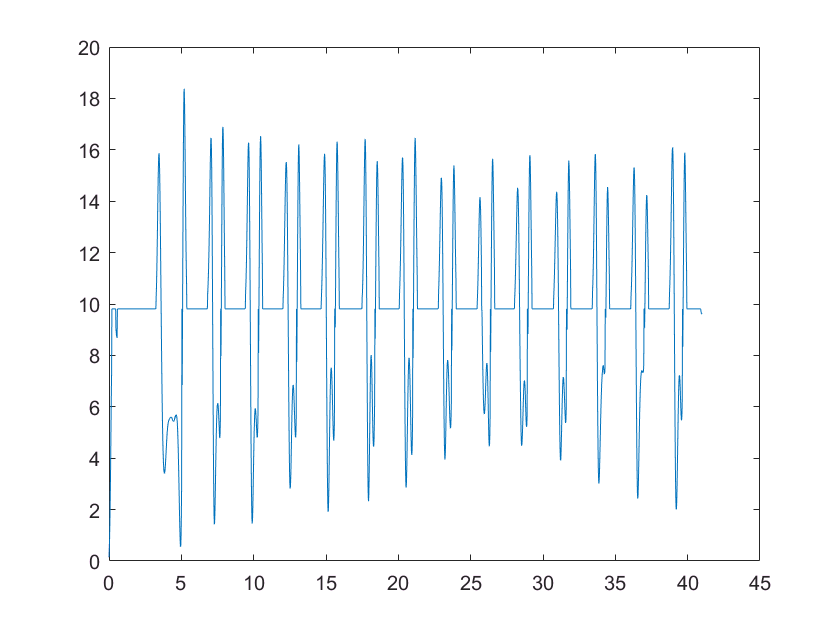

untouchedz = zacc;

% zeros the fuzz
for i = 1 : size(zacc)-4
    if(abs((zacc(i)- 9.81) < 1) && (abs((zacc(i + 2)- 9.81))< 1))
        zacc(i) = 9.81;
    end
end
 plot(x_times,zacc)

%finds beat one
 beatOne = []


beatOne =

     []



 for i = 3 : size(zacc)-4
    if((zacc(i)== 9.81) && (zacc(i-1)- 9.81 >0) && (zacc(i+ 1)== 9.81))
         beatOne = cat(1, beatOne, i);
    end
end
 beatOne

beatOne =          270
         402
         532
         664
         797
         935
        1067
        1201
        1334
        1463


 %find beat 3
 beatThree = []


beatThree =

     []



  for i = 3 : size(zacc)-4
    if((zacc(i)== 9.81) && (zacc(i+1)- 9.81 >0) && (zacc(i- 1)== 9.81))
         beatThree = cat(1, beatThree, i);
    end
end
 beatThree

beatThree =          163
         341
         472
         602
         734
         875
        1004
        1139
        1273
        1402


 
 beatThreeTimes =[]


beatThreeTimes =

     []



for i = 1 : size(beatThree)
    indexBeat = beatThree(i);
    beatThreeTimes(i) = x_times(indexBeat);
end
 
beatThreeTimes

beatThreeTimes =     3.2404    6.8008    9.4211   12.0214   14.6617   17.4820   20.0623   22.7626   25.4429   28.0232   30.7235   33.4038   36.0641   38.7244


 
 
 beatOneTimes =[]


beatOneTimes =

     []



for i = 1 : size(beatOne)
    indexBeat = beatOne(i);
    beatOneTimes(i) = x_times(indexBeat);
end
 
beatOneTimes

beatOneTimes =     5.3806    8.0209   10.6212   13.2615   15.9218   18.6821   21.3224   24.0027   26.6630   29.2433   31.9236   34.6039   37.3042   39.9445


 
 
 
 
% binarySignal = zacc < 2.5;
% leadingEdges1 = find(diff(binarySignal) >= 1);
% beatOneInd = leadingEdges1
% 
% % THIS MAKES THE ARRAY OF TIMES
% beatOneTimes =[]
% for i = 1 : size(beatOneInd)
%     indexBeat = beatOneInd(i);
%     beatOneTimes(i) = x_times(indexBeat);
% end
% beatOneTimes % THIS IS THE ARRAY OF TIMES

% beat error analysis
known_beat = 90;              % bpm
sec_per_beat = 60/known_beat; % seconds per beat
actual_bpm = 60./((beatOneTimes(2:end) - beatOneTimes(1:end-1))./4)

actual_bpm =    90.8988   92.2973   90.8988   90.2154   86.9467   90.8988   89.5421   90.2154   93.0127   89.5421   89.5421   88.8788   90.8988


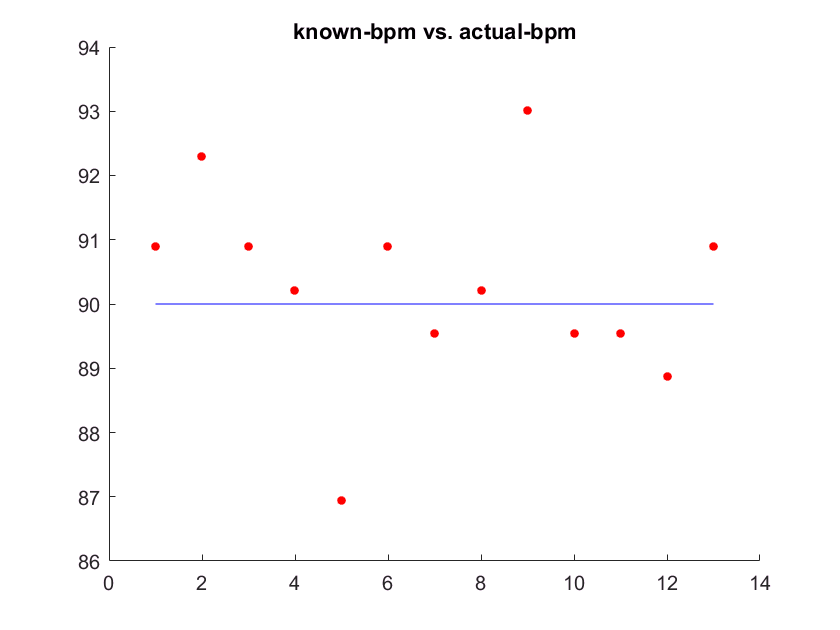


% plot error
figure
hold on
dot = 15;
plot(actual_bpm, 'r.', 'markersize', 15)
plot(known_beat.*ones(length(actual_bpm)), 'b-', 'markersize', 15)
title('known-bpm vs. actual-bpm')



binarySignal = zacc > 12;
leadingEdges4 = find(diff(binarySignal) >= 1);
beat4Ind = leadingEdges4

beat4Ind =    167
   256
   346
   390
   476
   520
   606
   652
   738
   784


%[Minima, MinIdx] = findpeaks(-zacc)


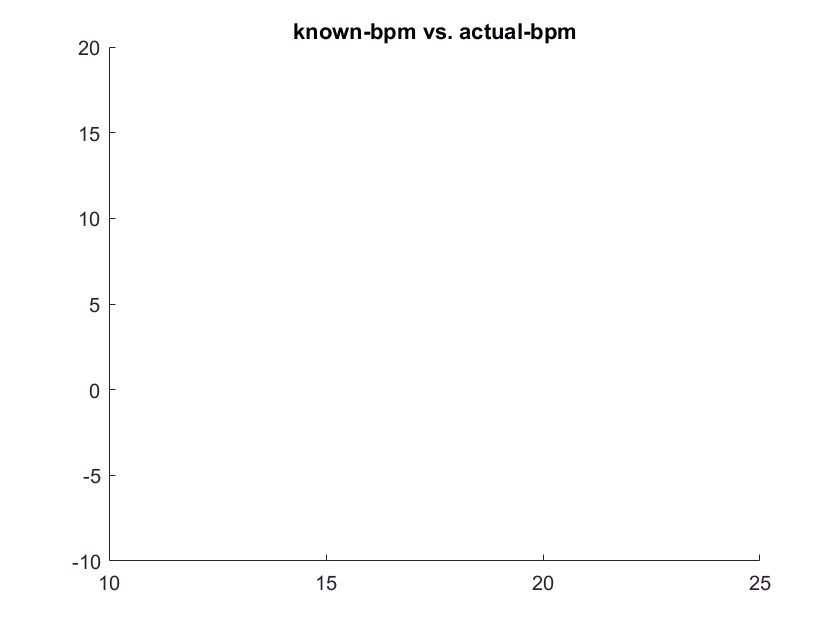

ylim([-10 20])
xlim([10 25])

x_times = square_accel(:,1);    % grab times column   % cutoff bad data
x_times = x_times-x_times(1);   % center unex times
x_accel_psquare = psquare_accel(1:end,2)

x_accel_psquare =     0.6091
    0.6151
    0.6741
    0.7339
    0.3067
    0.5402
    0.6174
    0.2225
    0.0997
    0.2281


figure
% plot(x_times, x_accel_psquare)
num = 8;
h = ones(1, num)./num;

%xacc = conv(xacc, h);
xacc = conv(x_accel_psquare, h);
%xacc = xacc(1:end-length(h)+1);
xacc = xacc(1:end-length(h)+1);

%plot(x_times,xacc)

Error using plot
Vectors must be the same length.


binarySignal = xacc > 1;
leadingEdges1 = find(diff(binarySignal) >= 1);
beatOneInd = leadingEdges1

% THIS MAKES THE ARRAY OF TIMES
beatOneTimes =[]
for i = 1 : size(beatOneInd)
    indexBeat = beatOneInd(i);
    beatOneTimes(i) = x_times(indexBeat);
end
beatOneTimes % THIS IS THE ARRAY OF TIMES